## $\sqrt{z}$ visualization

### Computing Square Root in MATLAB - sqrt($z$) vs $z^{1/2}$

Let try calling the default square root function, sqrt:

z = 1 + 3i;
r1 = sqrt(z)

r1 = 1.4426 + 1.0398i

Also, raise $z$ to a power of $\frac{1}{2}$:

r2 = z^(1/2)

r2 = 1.4426 + 1.0398i

Check that this number is a solution:

r2^2

ans = 1.0000 + 3.0000i

From **Theorem 2.2.6**, we know that $z^{\frac{1}{2}} = r^{\frac{1}{2}}\left[ \cos \frac{\theta}{2} + i\sin \frac{\theta}{2}\right]$ or considering multiple root $z^{\frac{1}{2}} = r^{\frac{1}{2}}\left[ \cos \frac{\theta+2k\pi}{2} + i\sin \frac{\theta+2k\pi}{2}\right]$ where $k=0,1$.

The principal argument of $z$ is:

arg = angle(z)/pi;
fprintf('The principal argument is = %f\\pi',arg)

The principal argument is = 0.397584\pi

Thus, for $k=0$:


$$z^{\frac{1}{2}} =$$


abs(z)^(1/2)*(cos(arg*pi/2)+1i*sin(arg*pi/2))

ans = 1.4426 + 1.0398i

corresponds to  $^{\frac{1}{2}}$ or sqrt function in MATLAB. For $k=1$:

sqrt($z$) =

abs(z)^(1/2)*(cos(arg*pi/2+pi)+1i*sin(arg*pi/2+pi))

ans = -1.4426 - 1.0398i

is not the default square root function in MATLAB.

### Constructing Square Root Function

Let's construct the square root function using what we learn in Complex Analysis.

Using **Definition 3.7.1 **(note that this is equivalent to Theorem 2.26), we have the principal branch as:

$\sqrt{|z|}\exp\left(\frac{i \text{Arg}(z)}{2}\right)$, so computing this explicitly, we have

r3 = sqrt(abs(z))*exp(1i*arg*pi/2)

r3 = 1.4426 + 1.0398i

Thus, the square root function defined by MATLAB is in fact, the principal branch.

To obtain the other solution, we use $\sqrt{|z|}\exp\left(\frac{i (\text{Arg}(z)+2\pi)}{2}\right)$:

r4 = sqrt(abs(z))*exp(1i*arg*pi/2+1i*pi)

r4 = -1.4426 - 1.0398i

### Standard Cut (Negative Real Axis)

From **Example 3.7.10**, we know that $z^{1/2}$ has only two branch points, i.e. $z=0$ and $z=\infty$.

So, the branch cut should be defined as a line (or curve) joining both branch points.

A standard (or commonly defined) branch cut is the *negative real axis*.

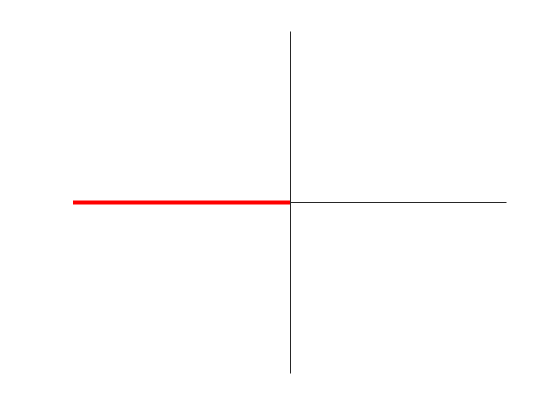

x = linspace(-100,0,100);
y = x.*0;
plot(x,y,'r','LineWidth',3);
% Setting
    ax = gca;
    ax.XAxisLocation = 'origin';
    ax.YAxisLocation = 'origin';
    ax.TickDir = 'out';
    xlim([-10 10]);
    ylim([-10 10]);
    set(ax, 'XTick', [], 'YTick', []);
    box off;

When we traverse in the path $z=Re^{i\theta}$ from $\theta=0$ to $\theta=3/2\pi$ (a partial circle), we expect a **discontinuity** at the branch cut. 

We verify this using MATLAB (you should be able to show this via mathematical calculation as well):

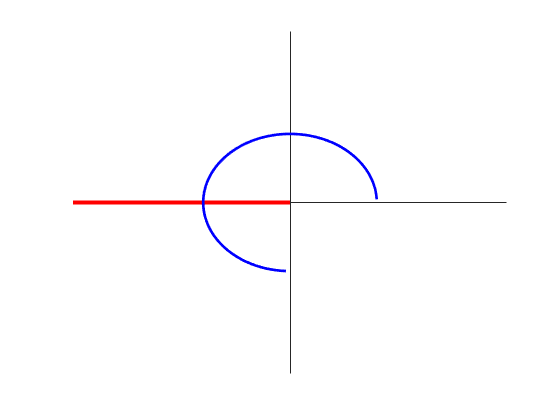

plot(x,y,'r','LineWidth',3);
hold on;

R = 4;
theta = linspace(0,3/2*pi,102); theta = theta(2:101);
z = R*exp(1i*theta);
plot(z,'b','LineWidth',2);
hold off;

% Setting
    ax = gca;
    ax.XAxisLocation = 'origin';
    ax.YAxisLocation = 'origin';
    ax.TickDir = 'out';
    xlim([-10 10]);
    ylim([-10 10]);
    set(ax, 'XTick', [], 'YTick', []);
    box off;    

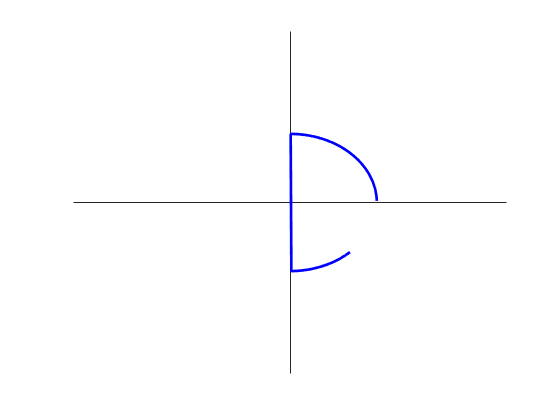

f = sqrt(z);
plot(f,'-b','LineWidth',2);
% Setting
    ax = gca;
    ax.XAxisLocation = 'origin';
    ax.YAxisLocation = 'origin';
    ax.TickDir = 'out';
    xlim([-5 5]);
    ylim([-5 5]);
    set(ax, 'XTick', [], 'YTick', []);
    box off;

### Positive Real Axis Cut

Since branch cut can be any line joining the two branch points, we can also defined the branch cut to be **positive real axis**. 

To define another branch cut, we define the following


$$\sqrt{z} = \sqrt{|z|}\exp\left(\frac{i \text{arg'}(z)}{2}\right)$$


where $\text{arg'}$ is the argument of $z$ (NOT principal argument!!!) and $0 < \text{arg'} \leq 2\pi$.

In order to do this, we must take note that the angle function in MATLAB returns a value between $-\pi$ to $\pi$. 

Thus, $\text{arg'}(z) = \text{mod}(\text{Arg}(z)+2\pi,2\pi)$.

Note, it is not: $\text{arg'}(z) = \text{Arg}(z) + \pi$.

Now, let plot the same graph as previous section with new branch cut.

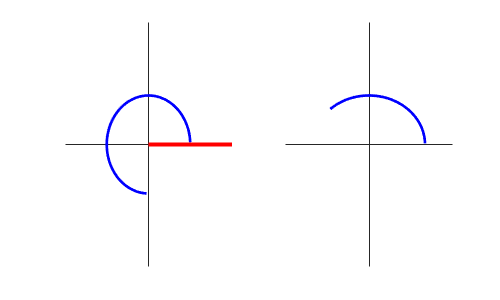

subplot(1,2,1);
plot(-x,y,'r','LineWidth',3);
hold on;

R = 4;
theta = linspace(0,1.5*pi,102); theta = theta(2:101);
z = R*exp(1i*theta);
plot(z,'b','LineWidth',2);
hold off;

% Setting
    ax = gca;
    ax.XAxisLocation = 'origin';
    ax.YAxisLocation = 'origin';
    ax.TickDir = 'out';
    xlim([-8 8]);
    ylim([-10 10]);
    set(ax, 'XTick', [], 'YTick', []);
    box off;
    
subplot(1,2,2);
f = sqrt(R)*exp(1i*(mod(angle(z)+2*pi,2*pi))/2);
plot(f,'-b','LineWidth',2);

% Setting
    ax = gca;
    ax.XAxisLocation = 'origin';
    ax.YAxisLocation = 'origin';
    ax.TickDir = 'out';
    xlim([-3 3]);
    ylim([-5 5]);
    set(ax, 'XTick', [], 'YTick', []);
    box off;

It is now continuous.